load('model1_mediation_N-109_X-expect_M-NPS_Y-outcome.mat')

### Select subjects

- Some subjects have too few trials to reliably estimate

- Arbitrary cutoff of 10 or more trials per person, after excluding outliers

- Leaves n = 100 subjects

% Count trials and select subjects
ntrials_trimmed = cellfun(@length, model1_Mtrimmed);

create_figure('ntrials', 1, 2); 
hist(ntrials_trimmed, 30)
title('Number of trials')
xlabel('Number of trials'); ylabel('Num. Subjects')

wh_remove = ntrials_trimmed < 10;
disp('removing:')

removing:


sum(wh_remove)

ans = 9

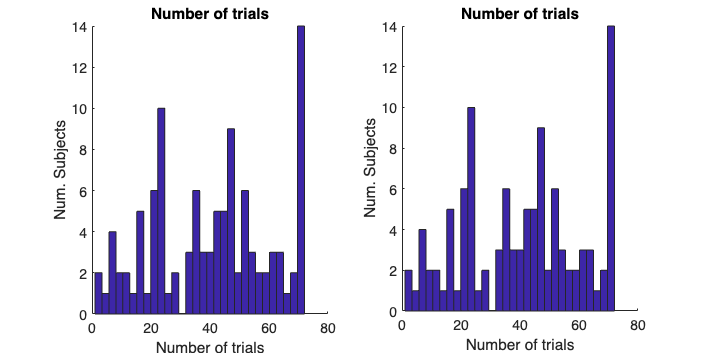


model1_X(wh_remove) = [];
model1_Xtrimmed(wh_remove) = [];
model1_Y(wh_remove) = [];
model1_Ytrimmed(wh_remove) = [];
model1_M(wh_remove) = [];
model1_Mtrimmed(wh_remove) = [];

cov_mediation_paincue_trimmed(wh_remove) = [];

subplot(1, 2, 2); hist(ntrials_trimmed, 30)
title('Number of trials')
xlabel('Number of trials'); ylabel('Num. Subjects')

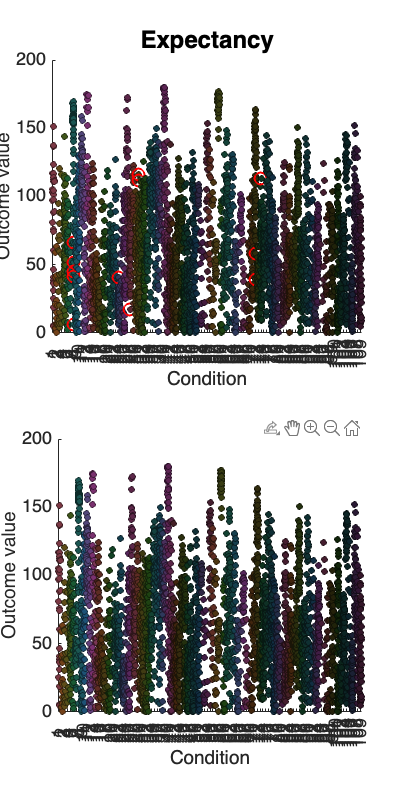

colors = seaborn_colors(length(model1_X))';

create_figure('X', 2, 1); 
barplot_columns(model1_X, 'nofig', 'noviolin', 'plotout', 'nostars', 'notable', 'colors', colors, 'nobars');
title('Expectancy');
subplot(2, 1, 2);
barplot_columns(model1_Xtrimmed, 'nofig', 'noviolin', 'nostars', 'notable', 'colors', colors, 'nobars');

drawnow, snapnow

create_figure('Y', 2, 1); 
barplot_columns(model1_Y, 'nofig', 'noviolin', 'plotout', 'nostars', 'notable', 'colors', colors, 'nobars');
title('Outcome (pain)');
subplot(2, 1, 2);
barplot_columns(model1_Ytrimmed, 'nofig', 'noviolin', 'nostars', 'notable', 'colors', colors, 'nobars');
drawnow, snapnow

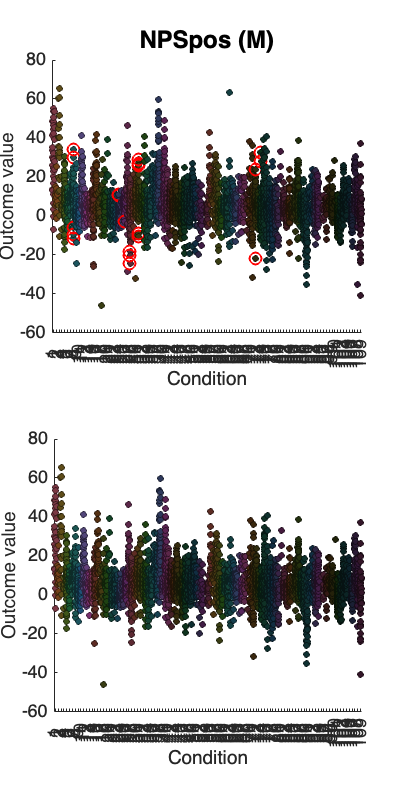

create_figure('M', 2, 1); 
barplot_columns(model1_M, 'nofig', 'noviolin', 'plotout', 'nostars', 'notable', 'colors', colors, 'nobars');
title('NPSpos (M)');
subplot(2, 1, 2);
barplot_columns(model1_Mtrimmed, 'nofig', 'noviolin', 'nostars', 'notable', 'colors', colors, 'nobars');

drawnow, snapnow


### Correlations between variables within- and between-person

meanx = cellfun(@nanmean, model1_X)';
meany = cellfun(@nanmean, model1_Y)';
meanm = cellfun(@nanmean, model1_M)';


create_figure('Expectation vs. Pain');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_X, model1_Y, 'n_bins', 5);

Warnings:

____________________________________________________________________________________________________________________________________________
X: input cells with low varability:
16 22 50 56 79
Y: input cells with low varability:
20 22 47 50 53
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.65 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, 

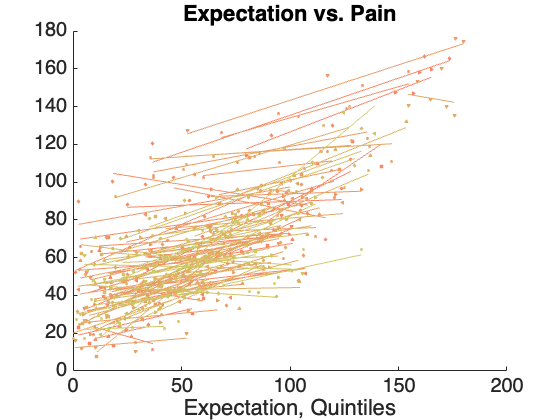

  title('Expectation vs. Pain');
  xlabel('Expectation, Quintiles');

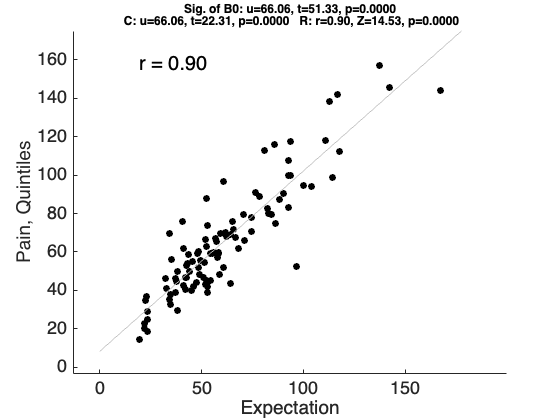


  figure; plot_correlation_samefig(meanx, meany, [], 'ko');
  xlabel('Expectation')
  ylabel('Pain, Quintiles')

create_figure('NPSpos vs. Pain');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_M, model1_Y, 'n_bins', 5);

Warnings:

____________________________________________________________________________________________________________________________________________
X: input cells with low varability:
24 37 43 52 79
Y: input cells with low varability:
20 22 47 50 53
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.20 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, 

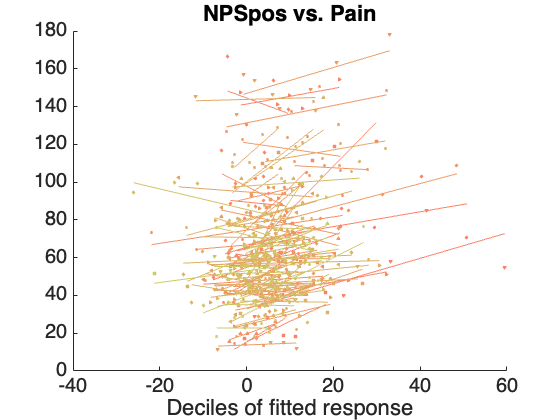

  title('NPSpos vs. Pain');
  xlabel('Deciles of fitted response');

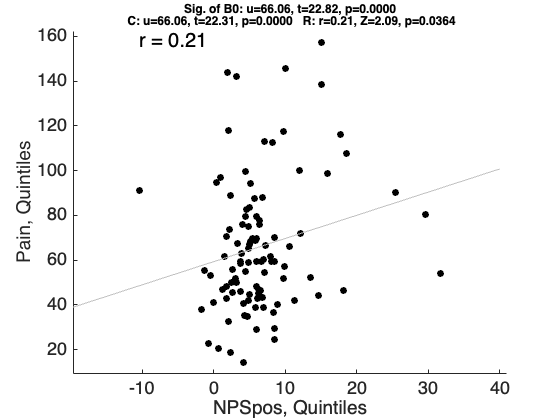


  figure; plot_correlation_samefig(meanm, meany, [], 'ko');
  xlabel('NPSpos, Quintiles')
  ylabel('Pain, Quintiles')

create_figure('Expectation vs. NPSpos');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_X, model1_M, 'n_bins', 5);

Warnings:

____________________________________________________________________________________________________________________________________________
X: input cells with low varability:
16 22 50 56 79
Y: input cells with low varability:
24 37 43 52 79
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.10 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, 

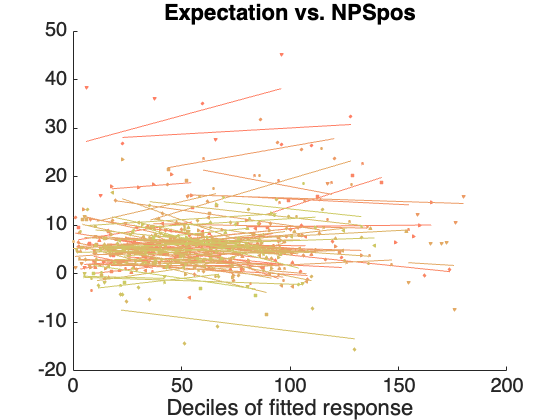

  title('Expectation vs. NPSpos');
  xlabel('Deciles of fitted response');

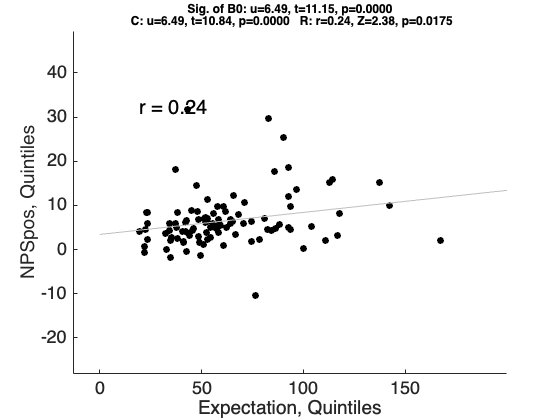


  figure; plot_correlation_samefig(meanx, meanm, [], 'ko');
  xlabel('Expectation, Quintiles')
  ylabel('NPSpos, Quintiles')


% partial correlations between expectancy, pain and NPSpos
partialr = partialcorr([meanx meany meanm]);

t = array2table(partialr, 'VariableNames', {'Expect' 'Pain' 'NPSpos'});
t

t = 3×3 table
    Expect        Pain         NPSpos  
    _______    __________    __________

          1        0.8958       0.11307
     0.8958             1    -0.0088454
    0.11307    -0.0088454             1


### Mediation analyses

Significant negative expectancy effect on NPS (Path a), consistent with prediction error (PE) signaling of NPS and reverse cue effect, and with threat analgesia effect on NPS. NPS is strongly related to pain (Path b). Both control for stim intensity. The average a and b effects are signficant, but the mediation effect (a*b) is not, because the negative within-person mediation effect (-a * b) is opposed by a positive between-person relationship between expectancy effects and pain: Participants with the most positive expectancy effects on NPS also have the most positive NPS-pain relationships (to verify...). This suggests that the threat analgesia effect (negative path from expectation ->NPS->pain) is moderated by individual differences.  Next, we include individual differences in nociceptive pain sensitivity (mean NPS) as a moderator.

Mediation analysis

Observations:   1, Replications: 100
Predictor (X): Expectation, Outcome (Y): Outcome rating: Mediator (M): NPSpos

Covariates: Yes, 100 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 100 Done.
Bootstrapping 10000 samples...

 Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   0 s 


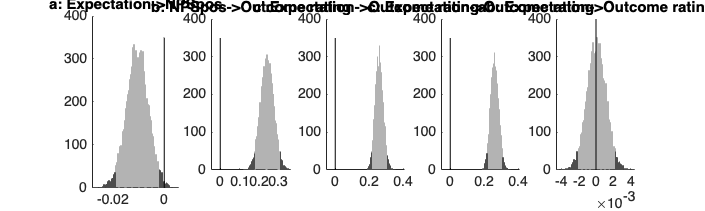

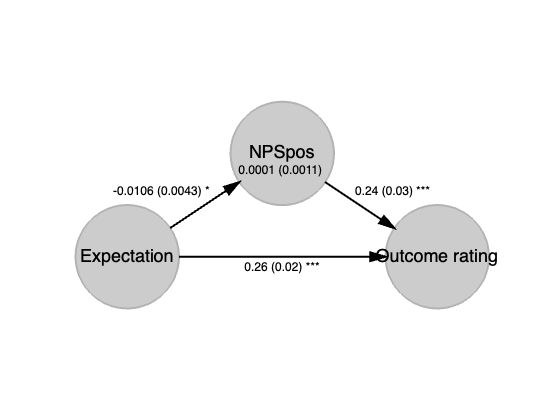

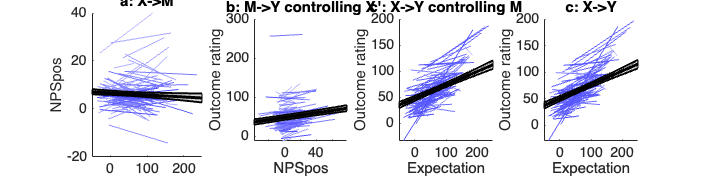

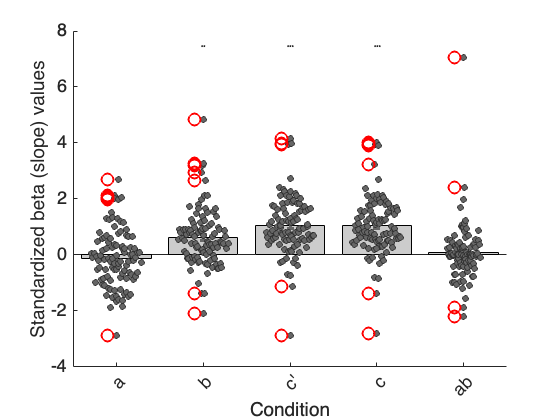

No second-level covariates; omitting 2nd level scatterplots.


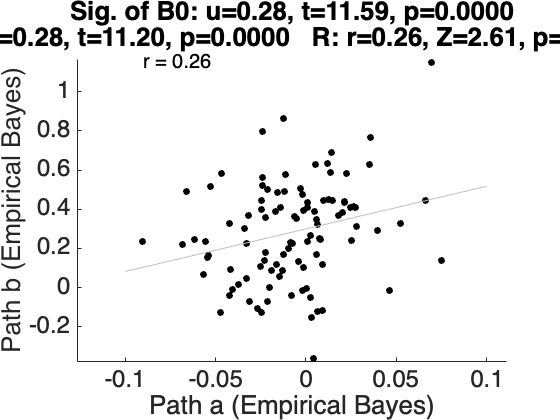


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	-0.01	0.24	0.26	0.26	0.00	
STE	0.00	0.03	0.02	0.02	0.00	
t (~N)	-2.46	7.17	11.04	11.05	0.05	
Z	-2.46	3.74	4.12	4.13	0.05	
p	0.0138	0.0002	0.0000	0.0000	0.9616	

________________________________________
Total time:   6 s


[paths_M_tolerance, stats_M_tolerance] = mediation(model1_Xtrimmed, model1_Ytrimmed, model1_Mtrimmed,'covs', cov_mediation_paincue_trimmed ,  'boot', 'verbose','plots', ...
    'names', {'Expectation' 'Outcome rating' 'NPSpos'},'bootsamples', 10000);

2nd-level moderation effects show that those with high pain sensitivty (NPSpos) show a more positive Expectancy-NPS relationship and stronger positive mediation effect, meaning that expectation is more hyperalgesic for these sensitive individuals. 

Mediation analysis

Observations:   1, Replications: 100
Predictor (X): Expectation, Outcome (Y): Outcome rating: Mediator (M): NPSpos

Covariates: Yes, 100 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 100 Done.
Bootstrapping 10000 samples... Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in  57 s 


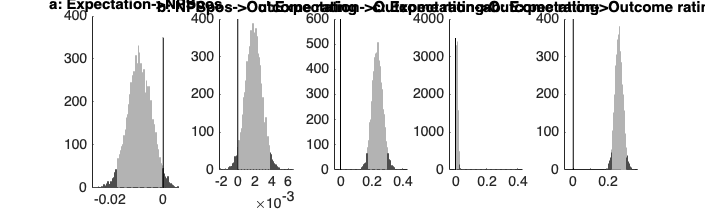

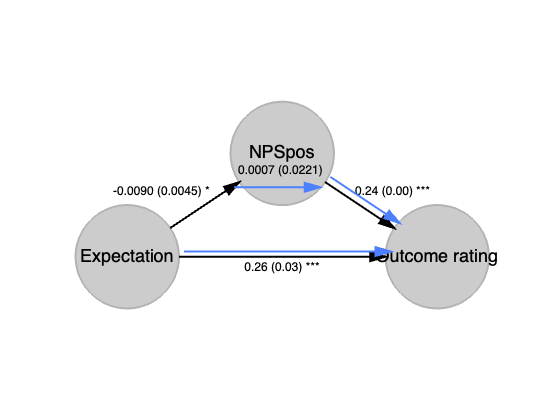

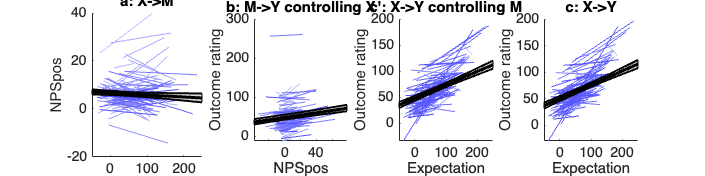

Mediation scatterplots:
Replications: 100
Covariates controlled for in all regressions: 100 predictors
Additional mediators controlled for in outcome predictions:   1 predictors


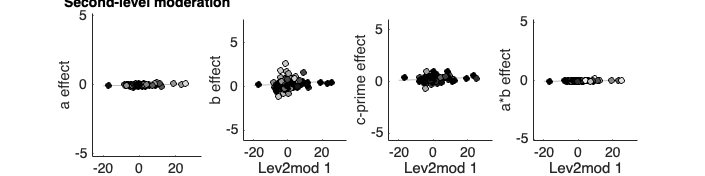


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	-0.01	0.24	0.26	0.26	0.00	
STE	0.00	0.03	0.02	0.02	0.00	
t (~N)	-2.00	6.96	11.78	11.77	0.57	
Z	-1.99	3.60	4.05	4.05	0.56	
p	0.0465	0.0003	0.0001	0.0001	0.5785	

________________________________________

________________________________________
Second Level Moderator
Multi-level model
	a	b	c'	c	ab	
Coeff	0.00	0.01	0.01	0.01	0.00	
STE	0.00	0.00	0.00	0.00	0.00	
t (~N)	1.90	2.54	1.69	1.98	2.60	
Z	1.93	2.92	2.04	2.38	2.60	
p	0.0540	0.0035	0.0410	0.0173	0.0094	

________________________________________
Total time:  64 s


moderator = scale(meanm, 1); 

[paths_M_tolerance, stats_M_tolerance] = mediation(model1_Xtrimmed, model1_Ytrimmed, model1_Mtrimmed,'covs', cov_mediation_paincue_trimmed ,  'boot', 'verbose','plots', ...
    'names', {'Expectation' 'Outcome rating' 'NPSpos'},'bootsamples', 10000, 'L2M', moderator);

# mediation analysis with Fear of pain

## load fear of pain questionnaire

/Users/h/Documents/projects_local/cue_expectancy/data/questionnaire/questionnaire_fear-of-pain.csv

## load NPS data